
load short_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);

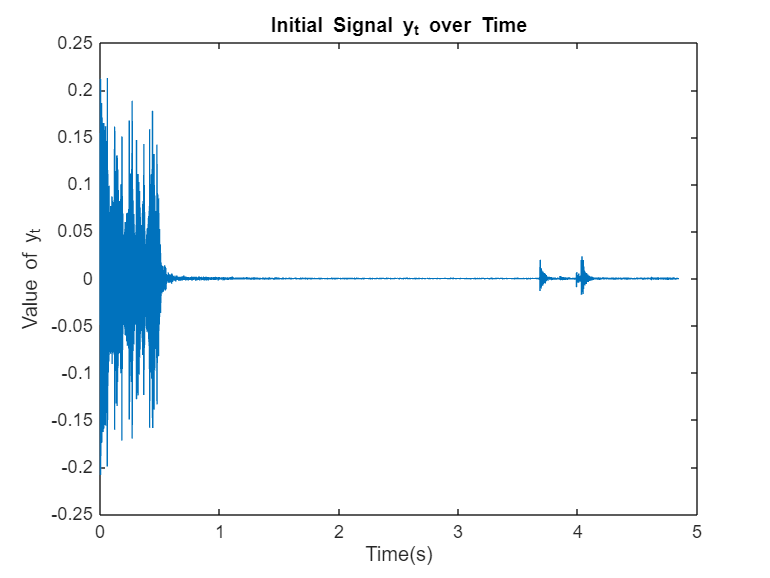

% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
t = (0:length(y_t)-1)'/Fs; 
plot(t, y_t)
title("Initial Signal y_t over Time")
xlabel("Time(s)")
ylabel("Value of y_t")

X =   -0.0370 + 0.0000i
  -0.0468 - 0.0010i
  -0.0577 + 0.0040i
  -0.0641 + 0.0205i
  -0.0570 + 0.0359i
  -0.0362 + 0.0622i
  -0.0174 + 0.0608i
   0.0049 + 0.0581i
   0.0328 + 0.0488i
   0.0486 + 0.0159i


f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


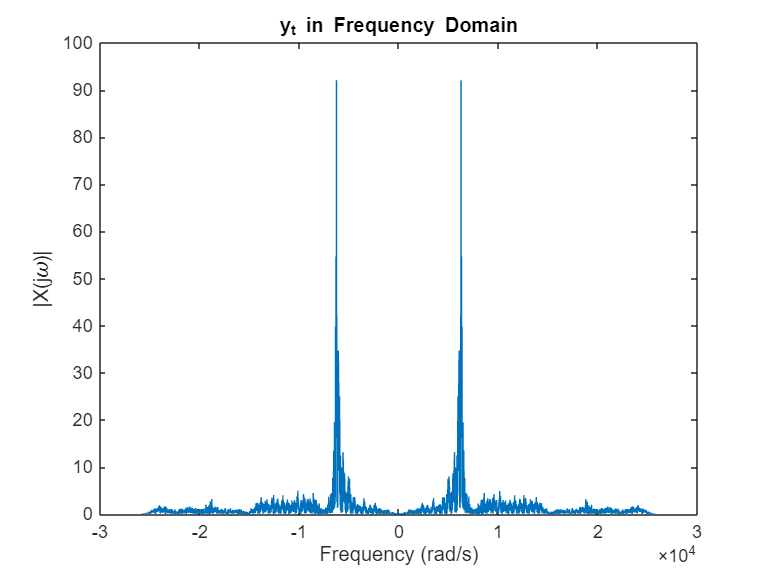

f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


X =   -0.0370 + 0.0000i
  -0.0468 - 0.0010i
  -0.0577 + 0.0040i
  -0.0641 + 0.0205i
  -0.0570 + 0.0359i
  -0.0362 + 0.0622i
  -0.0174 + 0.0608i
   0.0049 + 0.0581i
   0.0328 + 0.0488i
   0.0486 + 0.0159i



[f, X] = make_frequency_domain_plot(Fs, y_t, "y_t")

soundsc(y_t, Fs)

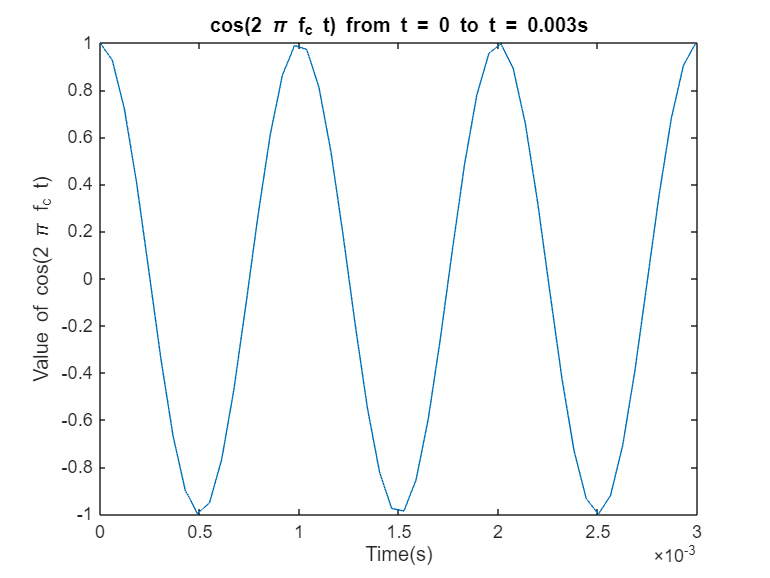


%% 
t_special = (0:length(y_t)-1)'/(Fs*2); 
cosinewave = cos(2*pi*f_c*t);
cosinewave_special = cos(2*pi*f_c*t_special);
plot(t_special(1:50), cosinewave_special(1:50))
title("cos(2 \pi f_c t) from t = 0 to t = 0.003s")
xlabel("Time(s)")
ylabel("Value of cos(2 \pi f_c t)")

X = 1.0e+04 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


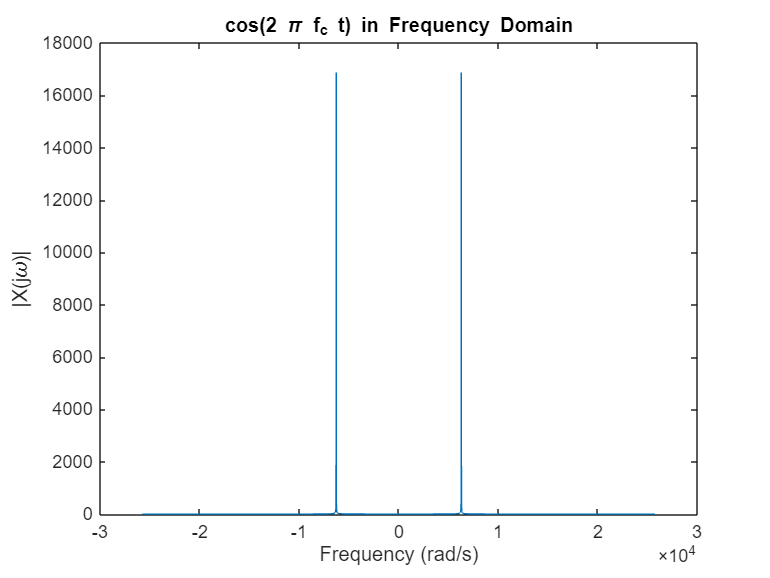

f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


X = 1.0e+04 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i




[f, X] = make_frequency_domain_plot(Fs, cosinewave, "cos(2 \pi f_c t)")

soundsc(cosinewave(1:4000), Fs)

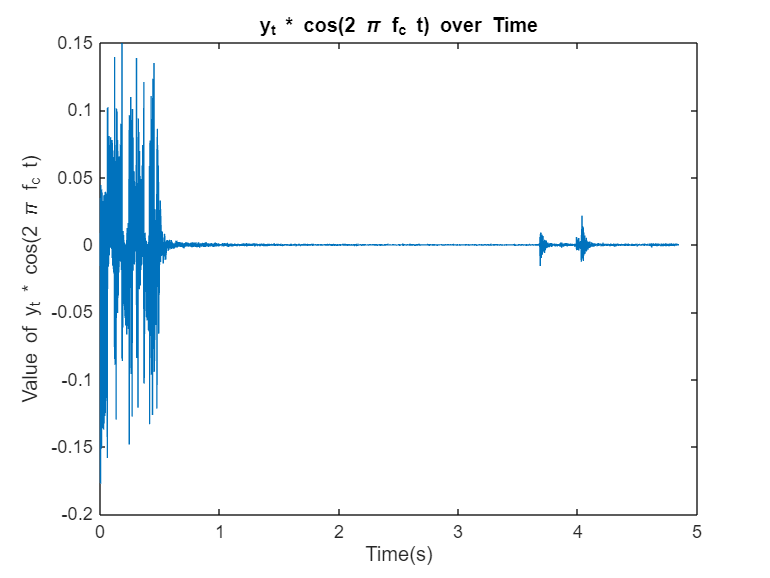

%% 

x_d = y_t .* cosinewave; 
plot(t, x_d)
title("y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Value of y_t * cos(2 \pi f_c t)")

X =   -0.0914 + 0.0000i
  -0.0037 + 0.1004i
   0.1201 + 0.1982i
   0.2338 + 0.2046i
   0.3002 + 0.1222i
   0.2833 + 0.0143i
   0.2520 - 0.0542i
   0.2101 - 0.0736i
   0.1309 - 0.0628i
   0.0938 + 0.0090i


f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


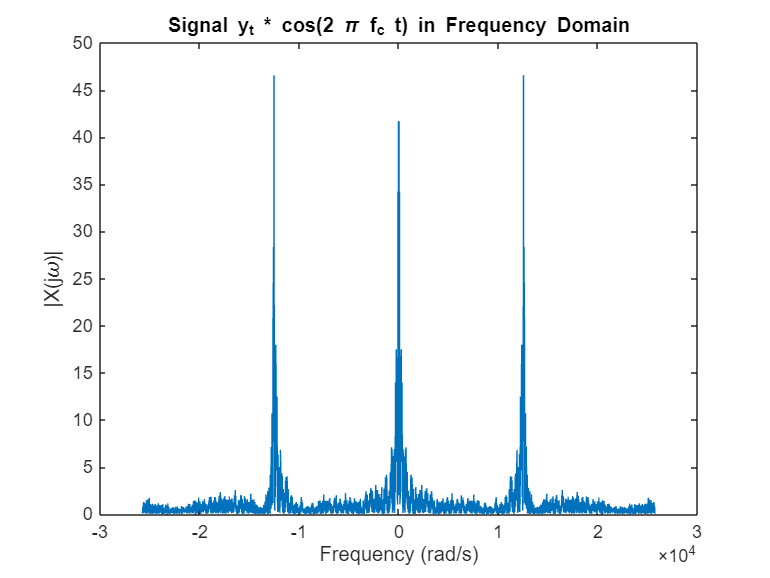

f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


X =   -0.0914 + 0.0000i
  -0.0037 + 0.1004i
   0.1201 + 0.1982i
   0.2338 + 0.2046i
   0.3002 + 0.1222i
   0.2833 + 0.0143i
   0.2520 - 0.0542i
   0.2101 - 0.0736i
   0.1309 - 0.0628i
   0.0938 + 0.0090i


[f, X] = make_frequency_domain_plot(Fs, x_d, "Signal y_t * cos(2 \pi f_c t)")

soundsc(x_d, Fs)

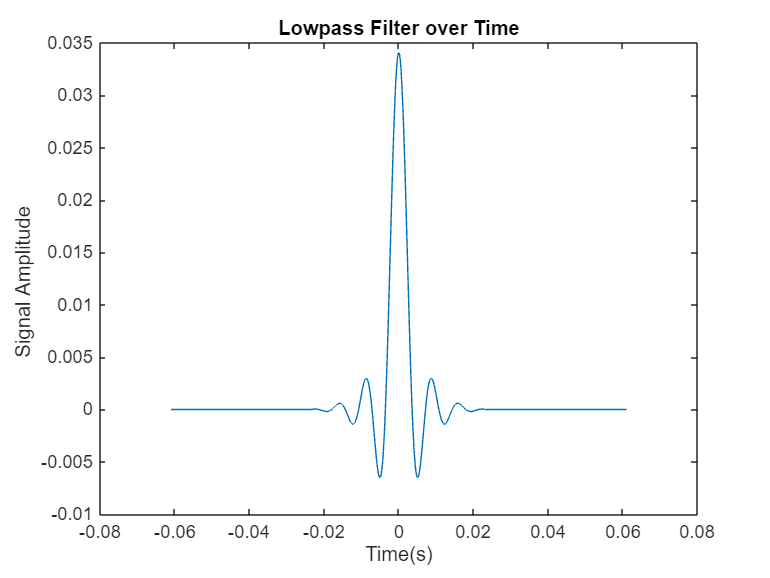

%% 

x_d_fil = lowpass(x_d,100,Fs,'Steepness',0.99);
%% 

lowpass_filter = lowpass([zeros([500 1]) ; 1 ; zeros([500 1])],100,Fs,'Steepness',0.99);
t_sp = (0:length(lowpass_filter)-1)'/Fs - ((length(lowpass_filter)-1)/Fs)/2;
plot(t_sp, lowpass_filter)
title("Lowpass Filter over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude ")

X =    0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i


f = 1.0e+04 *

   -2.5736   -2.5685   -2.5633   -2.5582   -2.5530   -2.5479   -2.5427   -2.5376   -2.5325   -2.5273   -2.5222   -2.5170   -2.5119   -2.5067   -2.5016   -2.4965   -2.4913   -2.4862   -2.4810   -2.4759   -2.4708   -2.4656   -2.4605   -2.4553   -2.4502   -2.4450   -2.4399   -2.4348   -2.4296   -2.4245   -2.4193   -2.4142   -2.4090   -2.4039   -2.3988   -2.3936   -2.3885   -2.3833   -2.3782   -2.3731   -2.3679   -2.3628   -2.3576   -2.3525   -2.3473   -2.3422   -2.3371   -2.3319   -2.3268   -2.3216


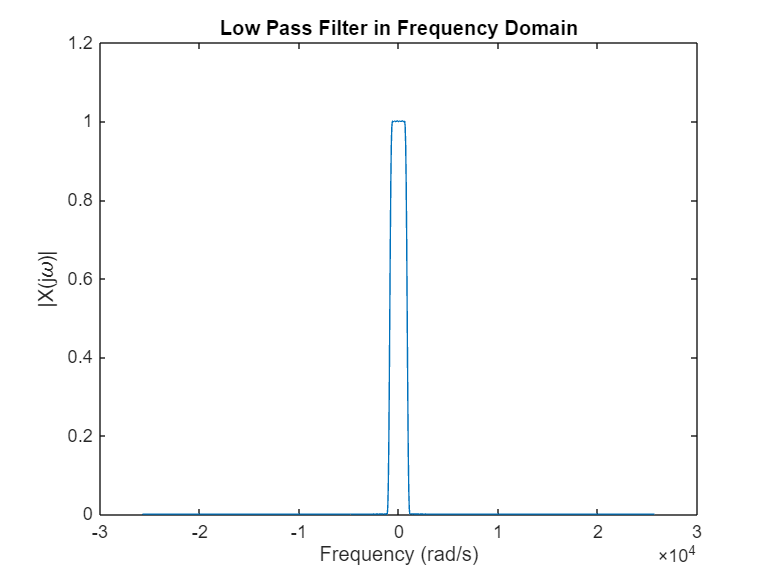

f = 1.0e+04 *

   -2.5736   -2.5685   -2.5633   -2.5582   -2.5530   -2.5479   -2.5427   -2.5376   -2.5325   -2.5273   -2.5222   -2.5170   -2.5119   -2.5067   -2.5016   -2.4965   -2.4913   -2.4862   -2.4810   -2.4759   -2.4708   -2.4656   -2.4605   -2.4553   -2.4502   -2.4450   -2.4399   -2.4348   -2.4296   -2.4245   -2.4193   -2.4142   -2.4090   -2.4039   -2.3988   -2.3936   -2.3885   -2.3833   -2.3782   -2.3731   -2.3679   -2.3628   -2.3576   -2.3525   -2.3473   -2.3422   -2.3371   -2.3319   -2.3268   -2.3216


X =    0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i





[f, X] = make_frequency_domain_plot(Fs, lowpass_filter, "Low Pass Filter")

soundsc(x_d_fil, Fs)

%% 
t_special2 = (1:1:length(x_d_fil))/Fs

t_special2 =     0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


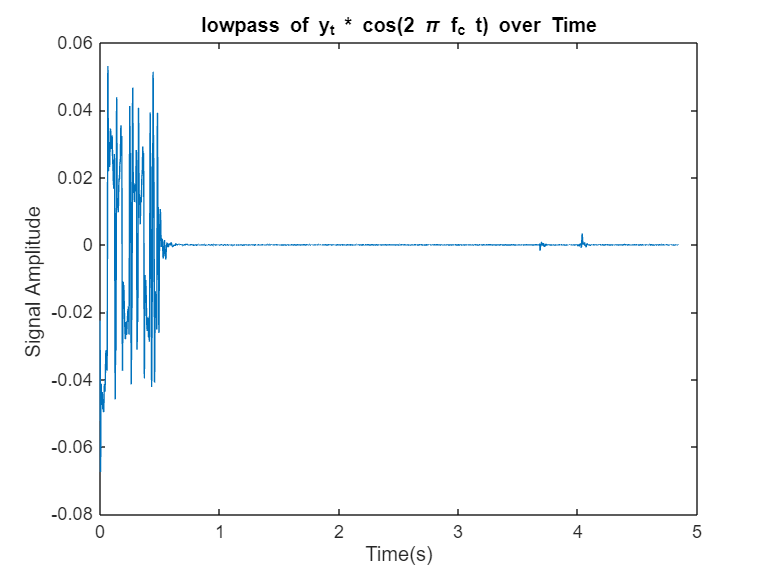

plot(t_special2, x_d_fil)
title("lowpass of y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude ")

X =   -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i


f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


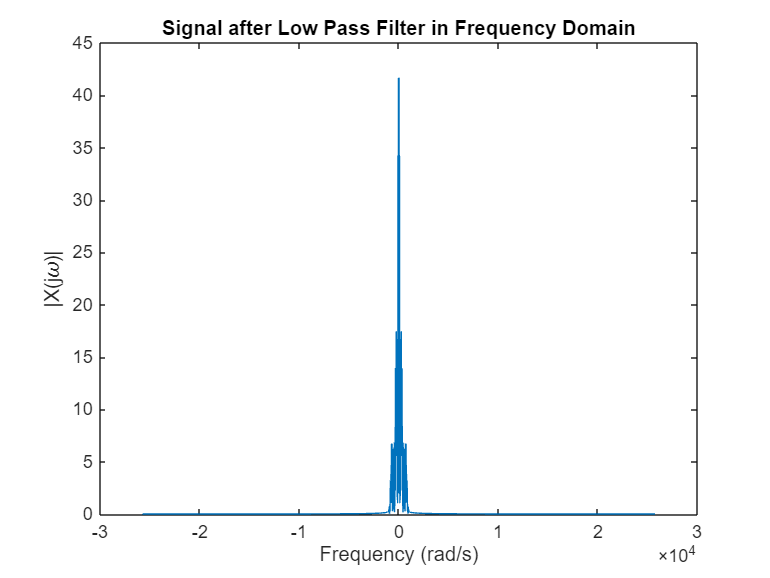

f = 1.0e+04 *

   -2.5736   -2.5735   -2.5733   -2.5732   -2.5731   -2.5729   -2.5728   -2.5727   -2.5726   -2.5724   -2.5723   -2.5722   -2.5720   -2.5719   -2.5718   -2.5716   -2.5715   -2.5714   -2.5713   -2.5711   -2.5710   -2.5709   -2.5707   -2.5706   -2.5705   -2.5703   -2.5702   -2.5701   -2.5700   -2.5698   -2.5697   -2.5696   -2.5694   -2.5693   -2.5692   -2.5691   -2.5689   -2.5688   -2.5687   -2.5685   -2.5684   -2.5683   -2.5681   -2.5680   -2.5679   -2.5678   -2.5676   -2.5675   -2.5674   -2.5672


X =   -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 + 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i
  -0.0107 - 0.0000i


[f, X] = make_frequency_domain_plot(Fs, x_d_fil, "Signal after Low Pass Filter")

soundsc(20.*x_d_fil, Fs)


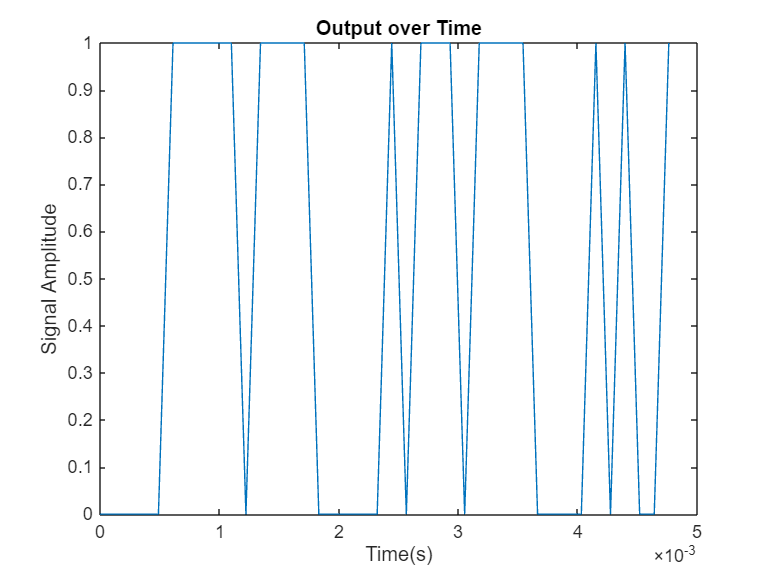

per = 100; 

mid_idx = (per/2):per:length(x_d_fil); % middle of each bit
s_vals = x_d_fil(mid_idx); % sampled values/bit
d_bit = s_vals > 0; % pos is 1 neg is 0

tot_bits = msg_length*8; % total bits

x_d = d_bit(1:tot_bits); % cut off extra bits at the end
t = (0:length(x_d)-1)'/Fs;
plot(t, x_d)
title("Output over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude")

X =    2.0000 + 0.0000i
  -2.4534 + 2.5089i
   1.8416 + 1.4425i
  -2.2479 + 1.5169i
  -3.6180 - 1.1756i
  -1.2929 - 1.1213i
   2.5095 - 2.2841i
  -2.4866 - 2.5889i
   0.6180 - 1.9021i
  -1.5788 + 0.3974i


f =  -257.3593 -244.4913 -231.6233 -218.7554 -205.8874 -193.0195 -180.1515 -167.2835 -154.4156 -141.5476 -128.6796 -115.8117 -102.9437  -90.0757  -77.2078  -64.3398  -51.4719  -38.6039  -25.7359  -12.8680         0   12.8680   25.7359   38.6039   51.4719   64.3398   77.2078   90.0757  102.9437  115.8117  128.6796  141.5476  154.4156  167.2835  180.1515  193.0195  205.8874  218.7554  231.6233  244.4913


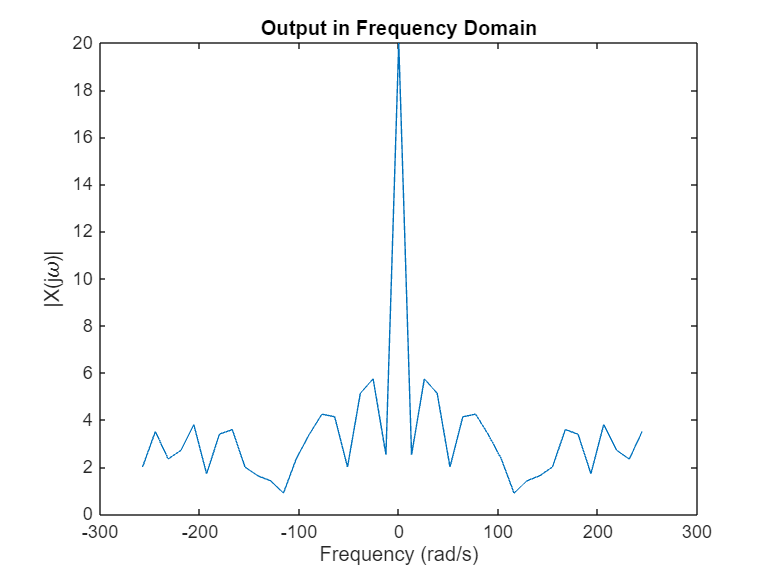

f =  -257.3593 -244.4913 -231.6233 -218.7554 -205.8874 -193.0195 -180.1515 -167.2835 -154.4156 -141.5476 -128.6796 -115.8117 -102.9437  -90.0757  -77.2078  -64.3398  -51.4719  -38.6039  -25.7359  -12.8680         0   12.8680   25.7359   38.6039   51.4719   64.3398   77.2078   90.0757  102.9437  115.8117  128.6796  141.5476  154.4156  167.2835  180.1515  193.0195  205.8874  218.7554  231.6233  244.4913


X =    2.0000 + 0.0000i
  -2.4534 + 2.5089i
   1.8416 + 1.4425i
  -2.2479 + 1.5169i
  -3.6180 - 1.1756i
  -1.2929 - 1.1213i
   2.5095 - 2.2841i
  -2.4866 - 2.5889i
   0.6180 - 1.9021i
  -1.5788 + 0.3974i



[f, X] = make_frequency_domain_plot(Fs/100, x_d, "Output")

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

soundsc(x_d*1.00, Fs)
% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits.
BitsToString(x_d)

ans = 'Hello'


function [f, X] = make_frequency_domain_plot(Fs, x, Algorithm)
    [X, f] = plot_ft_rad(x, Fs)
    title(Algorithm + ' in Frequency Domain')
end